# Taxi Deployment 

## Data Extraction and Introduction 

To get started, navigate to the Taxi Project folder, and run the script **generateTaxiPickupTable.mlx**. 

*Note it may take a while to finish. *

This will create (and save) two tables: `pickupLocations` and `taxiPickups. `A preview and description of each table is given below. 

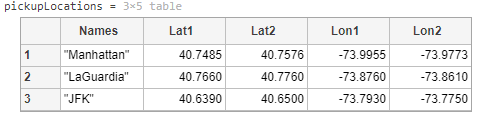

The table `pickupLocations` gives the latitude and logitude bounds for three pickup zones: 

- **Manhattan**: here meaning an area of high taxi traffic surrounding Penn Station, Grand Central Station, and the Port Authority Bus Terminal

- **LaGuardia**: meaning an area surrounding LaGuardia airport

- **JFK**: similarly meaning an area surrounding JFK airport. 

The zones are shown below for reference. 

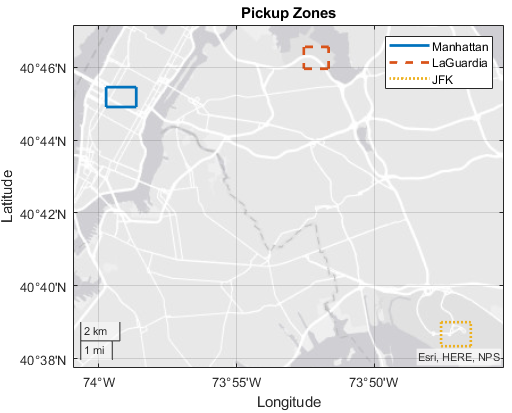

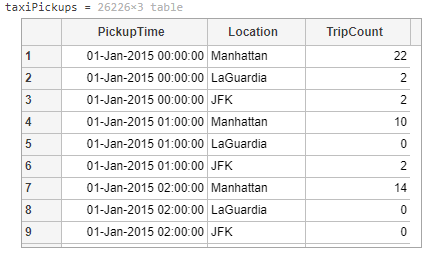

The table `taxiPickpus` represents the number of pickups in your data over one hour intervals of 2015 in the zones defined in `pickupLocations`. The start of each hour is specified in the `PickupTime` datetime variable, the zone is specified by the `Location` categorical variable, and the number of pickups is given by the `TripCount`. 

## Data Exploration and Partitioning 

The script **generateTaxiPickupTable.mlx **in the previous section saved copies of the tables to a MAT file named **taxiPickupData.mat**. To avoid having to run the script again if you continue working after clearing your workspace, the code below loads the saved data.

% run 'Module 3'\'Taxi Project'\generateTaxiPickupTable.mlx
clear
% Make sure to follow the instructions in the previous section
if ~isempty(which('-all','taxiPickupData.mat'))
    load taxiPickupData.mat 
else
    error("The file taxiPickupData.mat is not found on the MATLAB path. Add it to the path or run generateTaxiPickupTable.mlx to generate it.")
end

### Visualization and Analysis

Analyze the data in the `taxiPickups` table. At a minimum, provide a visualization of the distribution (histogram) of the response variable `TripCount`, as well as a box plot for `TripCount` grouped by `Location`. 

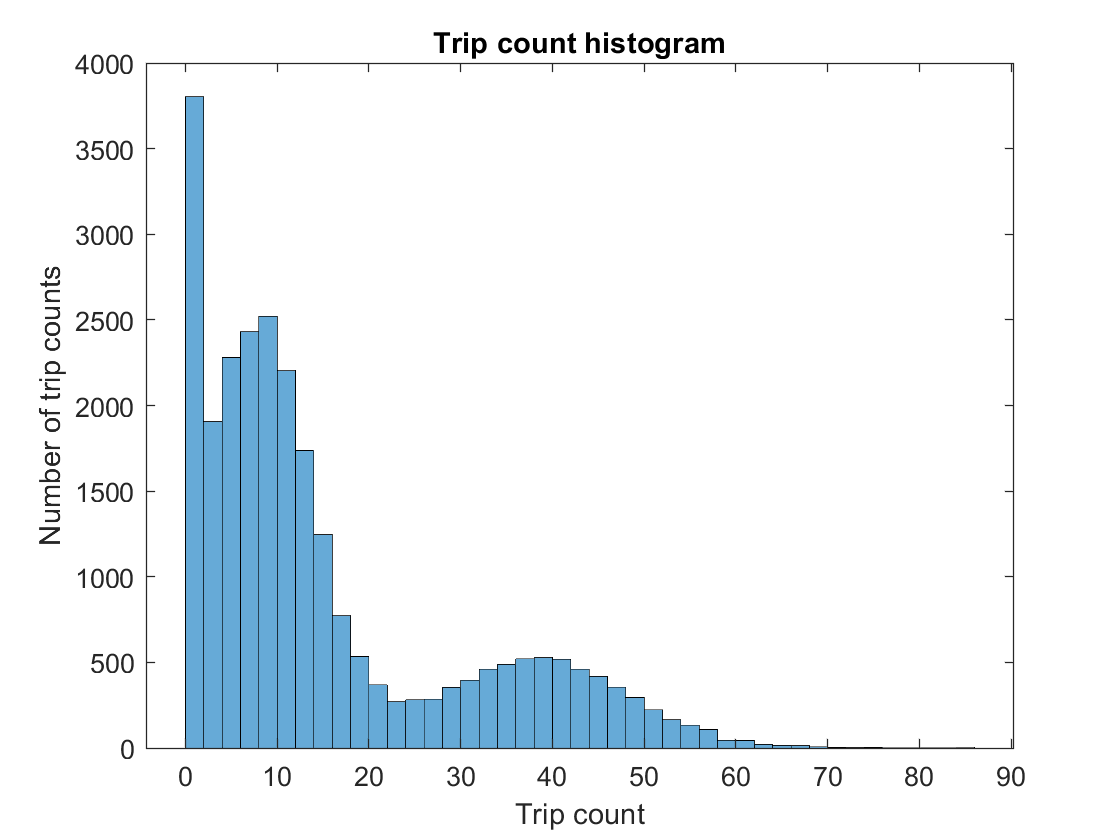

histogram(taxiPickups.TripCount)

title('Trip count histogram')
xlabel('Trip count')
ylabel('Number of trip counts')

grpLocation = groupsummary(taxiPickups,"Location","sum","TripCount")

grpLocation = 3×3 table
    Location     GroupCount    sum_TripCount
    _________    __________    _____________

    Manhattan       8739        2.6925e+05  
    LaGuardia       8739             66729  
    JFK             8739             56970  


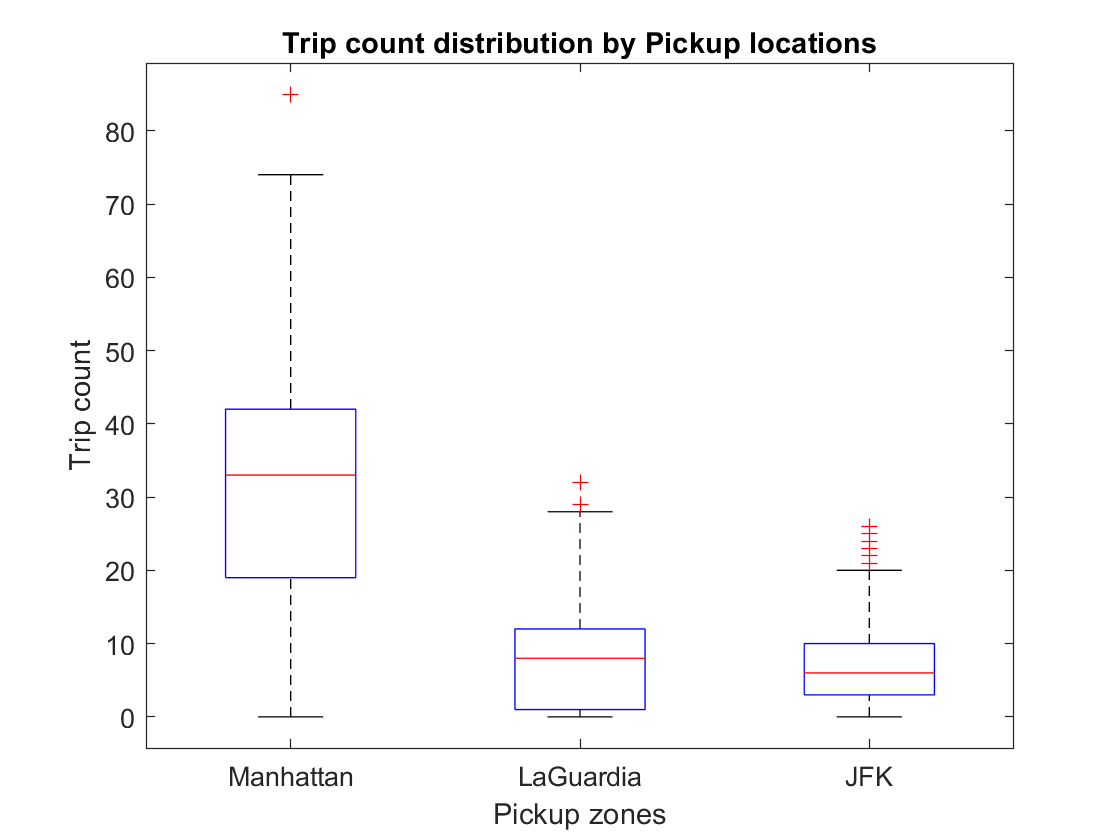

boxplot(taxiPickups.TripCount,taxiPickups.Location)
title('Trip count distribution by Pickup locations')
xlabel('Pickup zones')
ylabel('Trip count')

### Separate Test Data 

Use `cvpartition` to separate 20% of the data set for testing later on, and create the training data. Ensure your results are repeatable by setting the random number generator seed to 10. Provide your code. 

rng(10)
taxiPartitions = cvpartition(height(taxiPickups),"HoldOut",0.2);

taxiPickupsTrain = taxiPickups(training(taxiPartitions),:);
taxiPickupsTest = taxiPickups(test(taxiPartitions),:);

## Models Training and Validation 

### Preprocessing 

As the focus of this course is machine learning, we’ve provided a function to do some feature engineering for you. Use **providedPreprocessing.mlx **to add the following features to your training/validation data set:

- `TimeOfDay` (numerical)

- `DayOfWeek` (categorical)

- `DayOfMonth` (numerical)

- `DayOfYear` (numerical) 

For example: 

taxiPickupsTrain = providedPreprocessing(taxiPickupsTrain);
taxiPickupsTest = providedPreprocessing(taxiPickupsTest);
% regressionLearner

### Model Training

Train models to predict `TripCount` using the processed test/validation data. **Report your validation approach and validation**$RMSE$** for your best model**. Your goal will be to get a validation$RMSE$ at or below $4.9$. Include code so that your script can reproduce your final model, including the model training. **If using the app, export the training function** and include a correct call to it in your script. Note you do not need to include the generated training function code itself in your script, just a correct call to it. For example, if you'd trained a tree model in the app and exported the training function, you could include: 

[modelStruct, validationRMSE] = trainRegressionModel(taxiPickupsTrain)

modelStruct = struct with fields:
            predictFcn: @(x)ensemblePredictFcn(predictorExtractionFcn(x))
     RequiredVariables: {'DayOfMonth'  'DayOfWeek'  'DayOfYear'  'Location'  'TimeOfDay'}
    RegressionEnsemble: [1×1 classreg.learning.regr.RegressionBaggedEnsemble]
                 About: 'This struct is a trained model exported from Regression Learner R2021b.'
          HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE = 4.6200

myModel = modelStruct.RegressionEnsemble

myModel =   RegressionBaggedEnsemble
           PredictorNames: {'Location'  'TimeOfDay'  'DayOfWeek'  'DayOfMonth'  'DayOfYear'}
             ResponseName: 'Y'
    CategoricalPredictors: [1 3]
        ResponseTransform: 'none'
          NumObservations: 20974
               NumTrained: 206
                   Method: 'Bag'
             LearnerNames: {'Tree'}
     ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                  FitInfo: []
       FitInfoDescription: 'None'
           Regularization: []
                FResample: 1
                  Replace: 1
         UseObsForLearner: [20974×206 logical]


  Properties, Methods


The code below shows Regression model function after using Regression Learner app:

**Validation **$RMSE$: 

validationRMSE

validationRMSE = 4.6200

**Validation Method**:  Cross-validation, 5 folds

The figures below shows parameter optimization of bagged ensemble model using Regression Learner App.

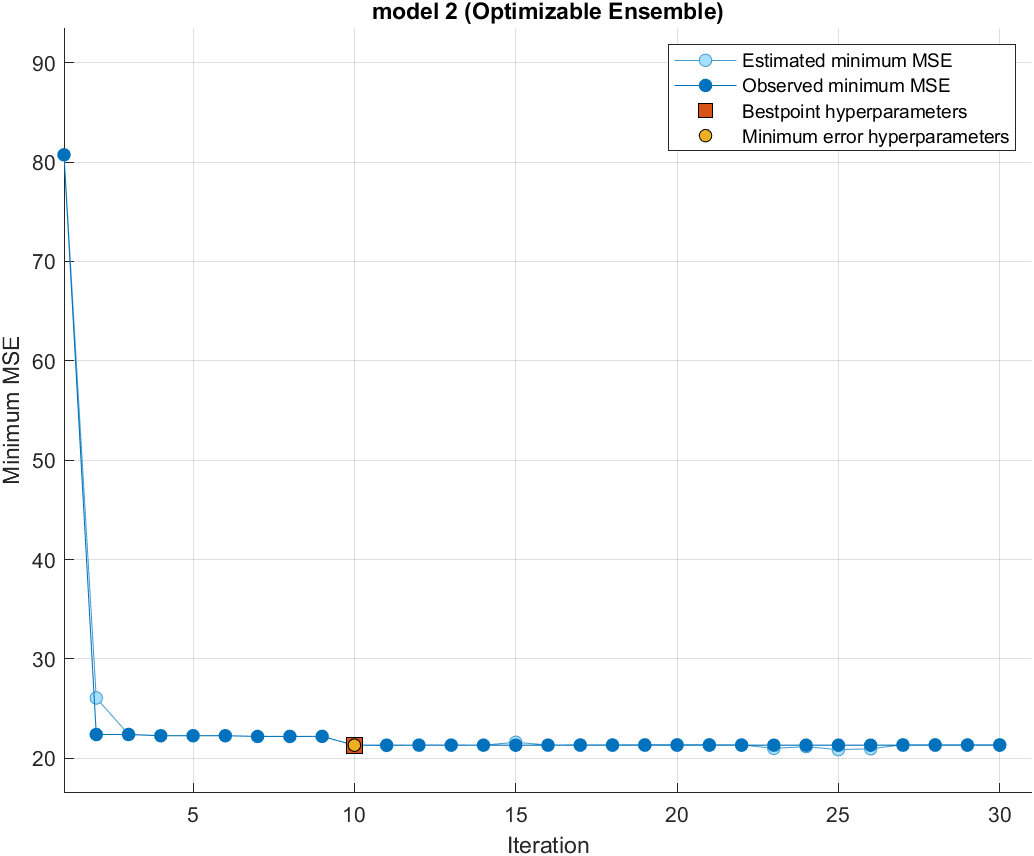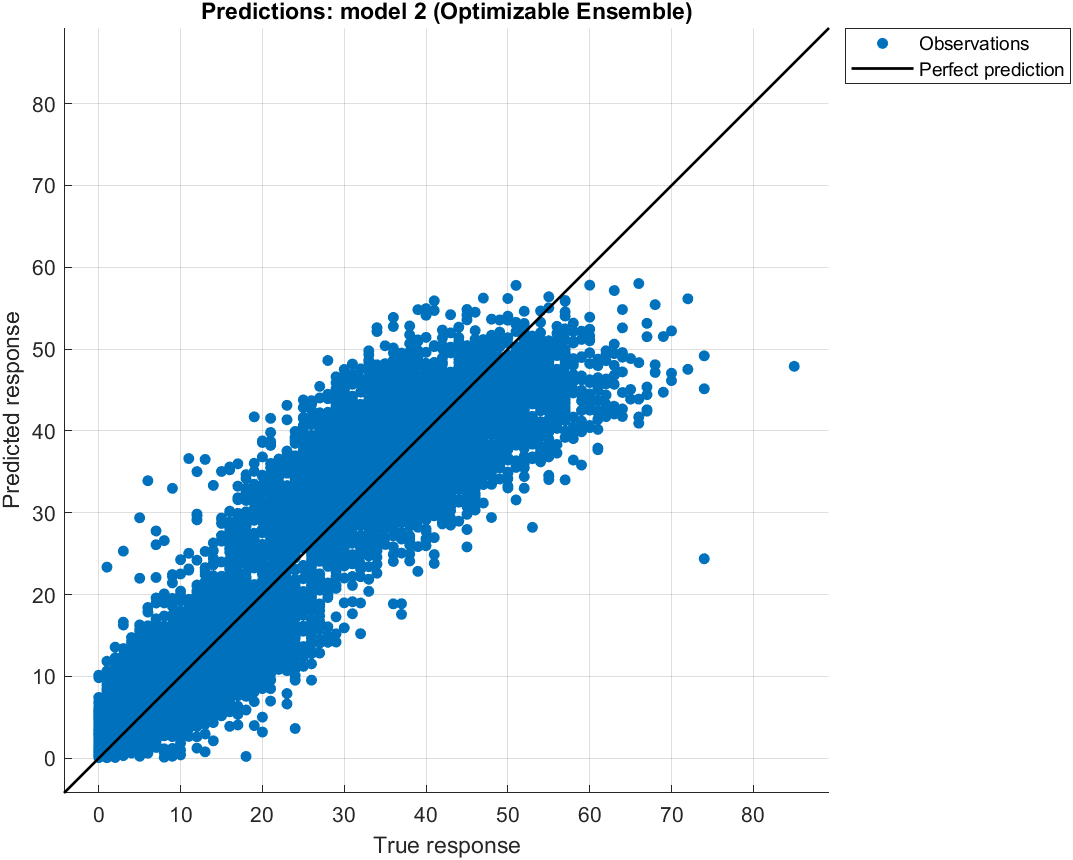

## Model Testing and Evaluation 

### Testing

Preprocess the test data as needed, and use it to test your best model. Provide your code and report at least the $RMSE$ and $R^2$. You will need to achieve a test $RMSE$ at or below $4.9$ to receive full points here. 

rMetrics(yActual,yPredict)

ans = 1×4 table
     mae       mse       rmse       Rsq  
    ______    ______    ______    _______

    3.1946    20.771    4.5576    0.90731


### Evaluation

Discuss the results from training and testing. How well did your model generalize to new data? Include at least a plot of the residuals, and discuss your observations from the plot(s). 

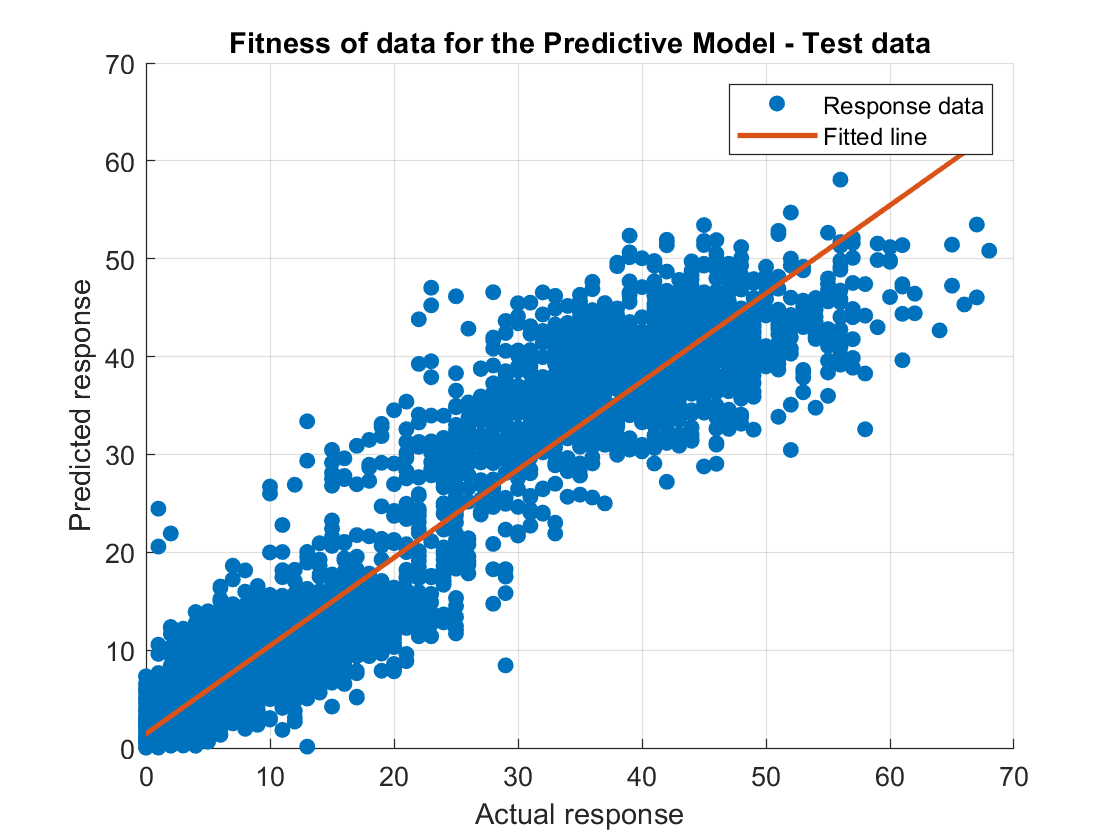

yPredict = predict(myModel,taxiPickupsTest);
yActual = taxiPickupsTest.TripCount;
yLine = polyval(polyfit(yActual,yPredict,1),yActual);
clf, hold on
scatter(yActual,yPredict,"filled","o")
plot(yActual,yLine,LineWidth=2)
hold off

grid on
legend({'Response data','Fitted line'})
title('Fitness of data for the Predictive Model - Test data')
xlabel('Actual response')
ylabel('Predicted response')

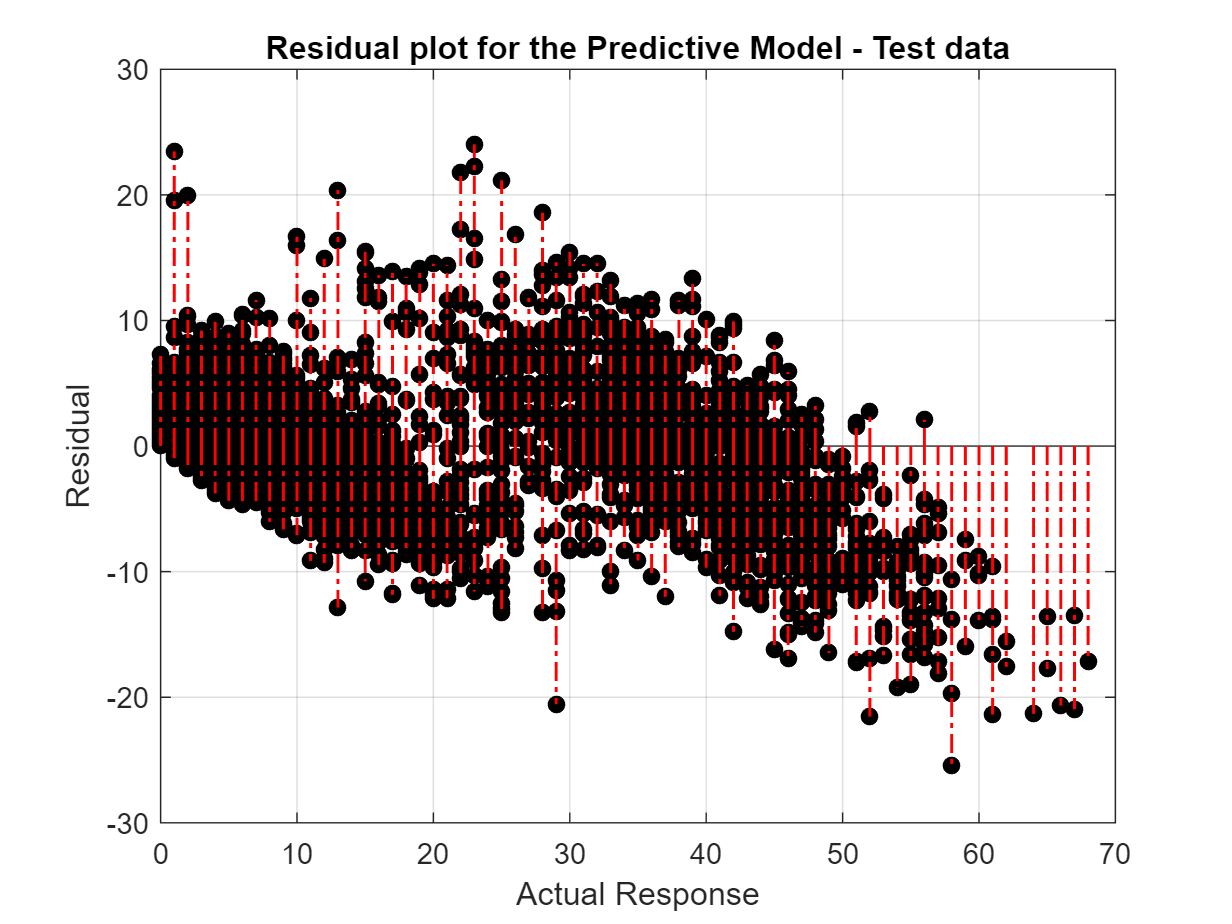

stem(yActual,yPredict-yActual,'LineStyle','-.','LineWidth',1,'color','red',...
     'MarkerFaceColor','black','MarkerEdgeColor','none')

grid on
title('Residual plot for the Predictive Model - Test data')
xlabel('Actual Response')
ylabel('Residual')

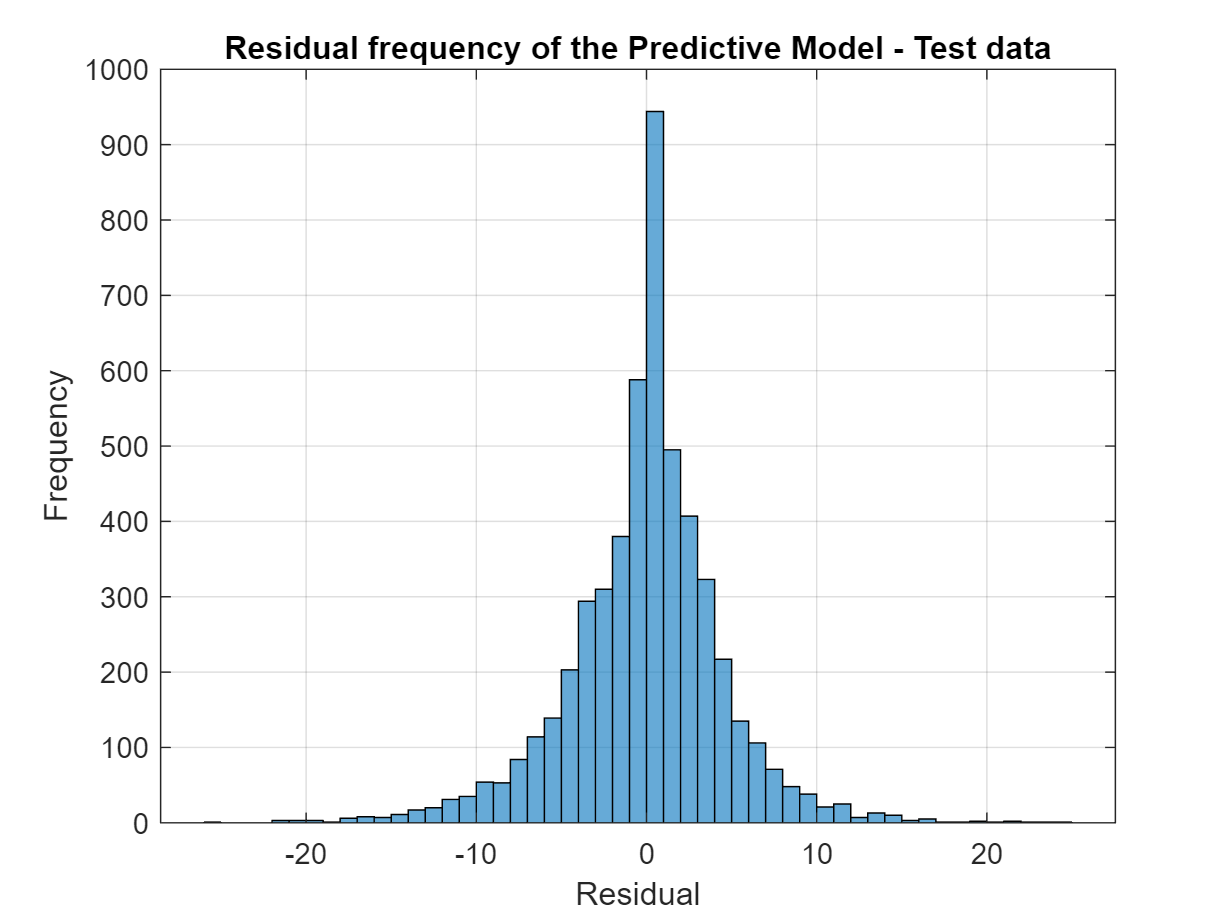

histogram(yPredict-yActual)

grid on
title('Residual frequency of the Predictive Model - Test data')
xlabel('Residual')
ylabel('Frequency')

The model predicts accurately within specification using the test data.

## Model Application, Results, and Analysis

### Apply Model 

As the focus of this course is machine learning, we’ve provided some skeleton code in this section. Below, we create a new table of staring features for 2016. 

*Note that you will need to use the variable names provided in comments or make your own additional edits to the code.*

taxiPickups2016 = table; 
taxiPickups2016.PickupTime = taxiPickups.PickupTime + years(1); 
taxiPickups2016.Location = taxiPickups.Location;
taxiPickups2016 = providedPreprocessing(taxiPickups2016); 
% Display only the first 8 rows of the table
head(taxiPickups2016)

ans = 8×6 table
        PickupTime         Location     TimeOfDay    DayOfWeek    DayOfMonth    DayOfYear
    ___________________    _________    _________    _________    __________    _________

    2016-01-01 05:49:12    Manhattan      5.82        Friday          1             1    
    2016-01-01 05:49:12    LaGuardia      5.82        Friday          1             1    
    2016-01-01 05:49:12    JFK            5.82        Friday          1             1    
    2016-01-01 06:49:12    Manhattan      6.82        Friday          1             1    
    2016-01-01 06:49:12    LaGuardia      6.82        Friday          1             1    
    2016-01-01 06:49:12    JFK            6.82        Friday          1             1    
    2016-01-01 07:49:12    Manhattan      7.82        Frida

Choose your favorite day in 2016 and edit the variable `myDay` below which will be used to extract that day from the table. 

myDay = datetime("2016-12-6")

myDay = datetime
   06-Dec-2016


taxiPickupsMyDay = taxiPickups2016(day(taxiPickups2016.PickupTime,"dayofyear") == day(myDay,"dayofyear"),:)

taxiPickupsMyDay = 72×6 table
        PickupTime         Location     TimeOfDay    DayOfWeek    DayOfMonth    DayOfYear
    ___________________    _________    _________    _________    __________    _________

    2016-12-06 00:49:12    Manhattan      0.82        Tuesday         6            341   
    2016-12-06 00:49:12    LaGuardia      0.82        Tuesday         6            341   
    2016-12-06 00:49:12    JFK            0.82        Tuesday         6            341   
    2016-12-06 01:49:12    Manhattan      1.82        Tuesday         6            341   
    2016-12-06 01:49:12    LaGuardia      1.82        Tuesday         6            341   
    2016-12-06 01:49:12    JFK            1.82        Tuesday         6            341   
    2016-12-06 02:49:12    Manhattan      2.8

Now, use your best model to predict `TripCount` on the day you've chosen and add it to the table. 

taxiPickupsMyDay.TripCount = predict(myModel,taxiPickupsMyDay);

Again, to focus on machine learning, we have provided the necessary table manipulations and calculations below to use your model predictions to give the predicted fraction of trips happening in each hour on your selected day. 

Uncomment below once you have defined the table `taxiPickupsMyDay` above. 

taxiPickupsMyDayTotals = groupsummary(taxiPickupsMyDay,"PickupTime","sum","TripCount");
taxiPickupsMyDay = join(taxiPickupsMyDay,taxiPickupsMyDayTotals,"RightVariables","sum_TripCount")

taxiPickupsMyDay = 72×8 table
        PickupTime         Location     TimeOfDay    DayOfWeek    DayOfMonth    DayOfYear    TripCount    sum_TripCount
    ___________________    _________    _________    _________    __________    _________    _________    _____________

    2016-12-06 00:49:12    Manhattan      0.82        Tuesday         6            341          8.401        12.328    
    2016-12-06 00:49:12    LaGuardia      0.82        Tuesday         6            341        0.32849        12.328    
    2016-12-06 00:49:12    JFK            0.82        Tuesday         6            341         3.5985        12.328    
    2016-12-06 01:49:12    Manhattan      1.82        Tuesday         6            341         5.

taxiPickupsMyDay.PickupFraction = taxiPickupsMyDay.TripCount./taxiPickupsMyDay.sum_TripCount

taxiPickupsMyDay = 72×9 table
        PickupTime         Location     TimeOfDay    DayOfWeek    DayOfMonth    DayOfYear    TripCount    sum_TripCount    PickupFraction
    ___________________    _________    _________    _________    __________    _________    _________    _____________    ______________

    2016-12-06 00:49:12    Manhattan      0.82        Tuesday         6            341          8.401        12.328            0.68146   
    2016-12-06 00:49:12    LaGuardia      0.82        Tuesday         6            341        0.32849        12.328           0.026646   
    2016-12-06 00:49:12    JFK            0.82        Tuesday         6            341         3.5985        12

taxiPickupsMyDayFractions = unstack(taxiPickupsMyDay,"PickupFraction","Location","GroupingVariables","PickupTime")

taxiPickupsMyDayFractions = 24×4 table
        PickupTime         Manhattan    LaGuardia      JFK   
    ___________________    _________    _________    ________

    2016-12-06 00:49:12     0.68146      0.026646      0.2919
    2016-12-06 01:49:12     0.91169     0.0070448    0.081261
    2016-12-06 02:49:12     0.93514     0.0059568    0.058899
    2016-12-06 03:49:12     0.90398     0.0068354    0.089188
    2016-12-06 04:49:12     0.79972      0.014616     0.18566
    2016-12-06 05:49:12     0.84623     0.0079198     0.14585
    2016-12-06 06:49:12     0.76236       0.12684      0.1108
    2016-12-06 07:49:12     0.72072        0.2003    0.078974
    2016-12-06 08:49:12     0.71279       0.23664    0.050571
    2016-12-06 09:49:12     0.68911       0.24536    0.065536
    2016-12-06 10:49:12     0.70912       0.21076    0.080123
    2016-12-06 11:

### Use the Results to Allocate Fleet

Now it is time to present to Mr. Walker. Discuss the results you were able to obtain, and provide recommendations how you would allocate the fleet of taxis on the chosen day. Provide your reasoning, and also present your case using at least one visualization, e.g. a [stacked bar plot](matlab: web(fullfile(docroot, 'matlab/ref/bar.html#bthxce9'))). 

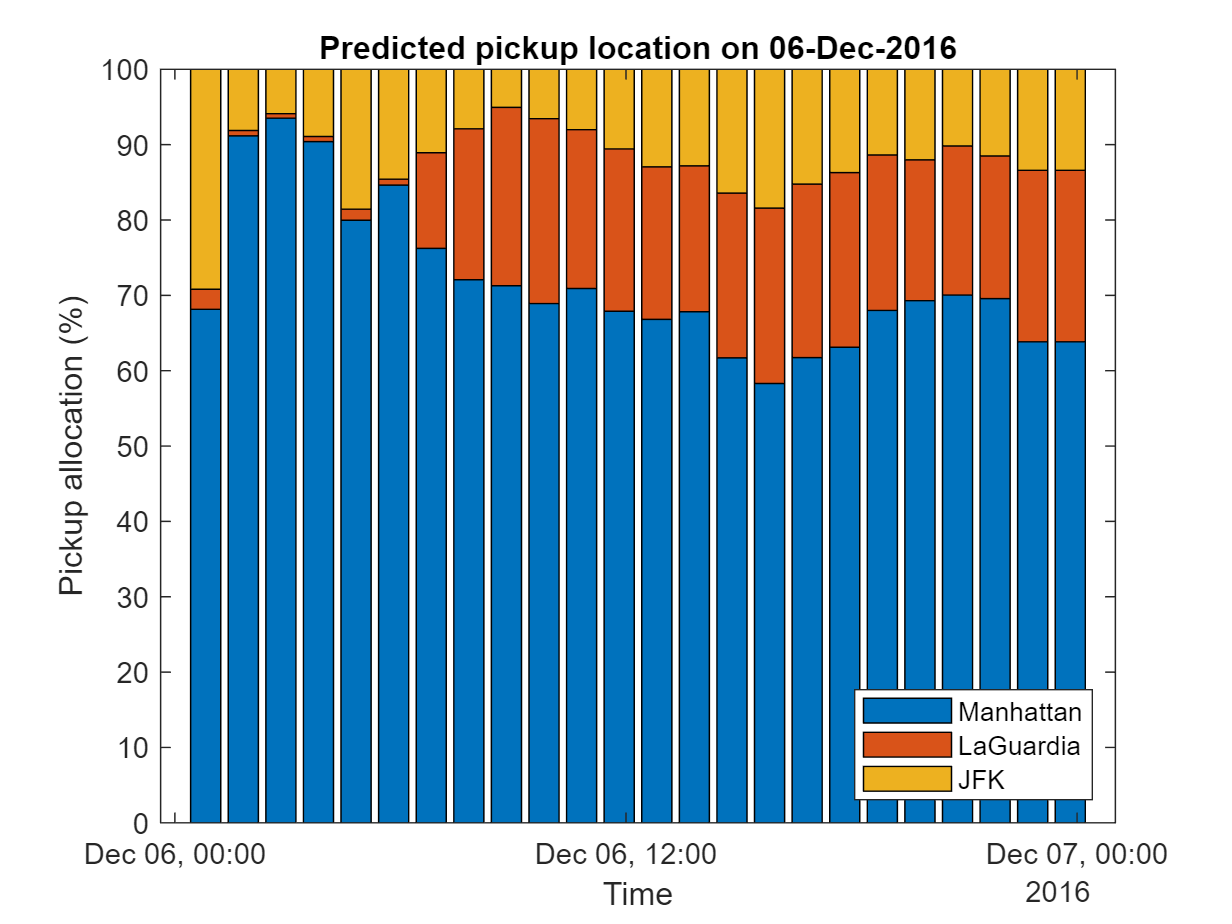

bar(taxiPickupsMyDayFractions.PickupTime,table2array(taxiPickupsMyDayFractions(:,2:end))*100,'stacked')

ylim([0 100])
xlabel('Time')
ylabel('Pickup allocation (%)')
title('Predicted pickup location on '+string(myDay))
legend(taxiPickupsMyDayFractions.Properties.VariableNames(2:end),Location="southeast")

- Manhattan taxi pickups is highest all the time

- Taxi pickups for JFK start reducing after 7:00 AM compares to LaGurdia.